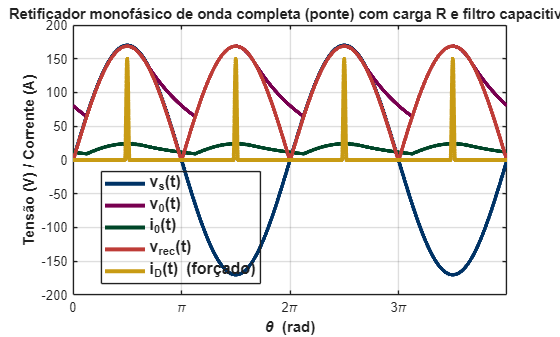

%% Retificador monofásico de ONDA COMPLETA (ponte) + carga R + filtro capacitivo

clear; clc; close all;

f   = 60;
Vm  = 170;
R   = 7;
C   = 670e-6;
Vd  = 0.7;
ncy = 12;
fs  = 200e3;

T  = 1/f;
dt = 1/fs;
t  = 0:dt:(ncy*T);
N  = numel(t);

omega = 2*pi*f;
theta = omega*t;
v_s   = Vm*sin(theta);

v_rec = abs(v_s) - 2*Vd;
v_rec(v_rec < 0) = 0;

v_0 = zeros(1,N);
for k = 2:N
    if v_rec(k) > v_0(k-1)
        v_0(k) = v_rec(k);
    else
        v_0(k) = v_0(k-1)*exp(-dt/(R*C));
    end
end

i_0 = v_0 / R;

Ipk   = 150;
Delta = 0.02*(T/2);

t_peaks = (pi/2 + pi*(0:ceil(2*ncy)))/omega;
t_peaks = t_peaks(t_peaks >= t(1) & t_peaks <= t(end));

i_D = zeros(size(t));

for kk = 1:numel(t_peaks)
    t0  = t_peaks(kk);
    tau = t - t0;

    m = abs(tau) <= Delta;

    g = zeros(size(t));
    g(m) = 0.5*(1 + cos(pi*tau(m)/Delta));

    i_D = i_D + Ipk*g;
end

statale.maincolor = [0   51  102]/255;
statale.lilla     = [120 0   80 ]/255;
statale.darkgreen = [0   70  40 ]/255;
statale.red       = [190 60  55 ]/255;
statale.yellow    = [200 155 20 ]/255;

plotColors = [
    statale.maincolor
    statale.lilla
    statale.darkgreen
    statale.red
    statale.yellow
];
set(groot,'defaultAxesColorOrder',plotColors);

LW = 3.0;

plotCycles = [6 7];
c1 = plotCycles(1);
c2 = plotCycles(2);

t1 = (c1-1)*T;
t2 = c2*T;

idx = (t >= t1) & (t <= t2);

thetaP   = theta(idx);
thetaRel = thetaP - thetaP(1);

vsP   = v_s(idx);
vrecP = v_rec(idx);
v0P   = v_0(idx);
i0P   = i_0(idx);
iDP   = i_D(idx);

figure('Color','w');
plot(thetaRel, vsP,   'Color', plotColors(1,:), 'LineWidth', LW); hold on;
plot(thetaRel, v0P,   'Color', plotColors(2,:), 'LineWidth', LW);
plot(thetaRel, i0P,   'Color', plotColors(3,:), 'LineWidth', LW);
plot(thetaRel, vrecP, 'Color', plotColors(4,:), 'LineWidth', LW);
plot(thetaRel, iDP,   'Color', plotColors(5,:), 'LineWidth', LW);
grid on;

xlabel('\theta (rad)');
ylabel('Tensão (V) / Corrente (A)');
title('Retificador monofásico de onda completa (ponte) com carga R e filtro capacitivo');

xlim([0, thetaRel(end)]);
k2 = floor(thetaRel(end)/pi);
xt = (0:k2)*pi;
xticks(xt);

m = 0:k2;
labs = strings(size(m));
for kk = 1:numel(m)
    if m(kk) == 0
        labs(kk) = "0";
    elseif m(kk) == 1
        labs(kk) = "\pi";
    else
        labs(kk) = sprintf('%g\\pi', m(kk));
    end
end
xticklabels(labs);

lgd = legend('v_s(t)','v_0(t)','i_0(t)','v_{rec}(t)','i_D(t) (forçado)', 'Location','best');
lgd.FontSize   = 12;
lgd.FontWeight = 'bold';
lgd.Color      = 'none';

ax = gca;
ax.XLabel.FontWeight = 'bold';
ax.YLabel.FontWeight = 'bold';